# Multivariate patterns from Silvestrini et al.

### Citation:

[Silvestrini, Nicolas, Jen-I Chen, Mathieu Piché, Mathieu Roy, Etienne Vachon-Presseau, Choong-Wan Woo, Tor .D. Wager, and Pierre Rainville. 2020. “Distinct fMRI Patterns Colocalized in the Cingulate Cortex Underlie the after-Effects of Cognitive Control on Pain.” ](http://Silvestrini, Nicolas, Jen-I Chen, Mathieu Piché, Mathieu Roy, and Etienne Vachon-. n.d. “Distinct fMRI Patterns Colocalized in the Cingulate Cortex Underlie the after-Effects of Cognitive Control on Pain.” https://www.sciencedirect.com/science/article/pii/S1053811920303840)

[https://doi.org/10.1016/j.neuroimage.2020.116898.](https://doi.org/10.1016/j.neuroimage.2020.116898.)

### Images

This repository includes 3 images. Each is a map trained using a Support Vector Machine (SVM) to be sensitive to Stroop task demand (incompatible - compatible) or shock pain (pain - rest) within a pre-defined mask.

We used linear support vector machines (SVMs) ([Vapnik, 2013](https://www.sciencedirect.com/science/article/pii/S1053811920303840#bib34)) to train multivariate pattern classifiers within aMCC for the task and the shocks. The task-related aMCC mask corresponded to an a priori meta-analytic map including aMCC activity induced by pain, cognitive control, and negative affect ([Shackman et al., 2011](https://www.sciencedirect.com/science/article/pii/S1053811920303840#bib30)) (data retrieved from [http://neurovault.org](http://neurovault.org/)). The shock-related aMCC mask consisted of the conjunction of the previous meta-analytic map with the NPS to obtain an aMCC subregion of the NPS. The SVMs were implemented using custom Matlab code based on the Spider toolbox ([http://people.kyb.tuebingen.mpg.de/spider](http://people.kyb.tuebingen.mpg.de/spider)). The pattern classifiers were trained on first-level contrast images for the two experimental conditions to discriminate the high and the low demand condition during the task and during the shocks.

**dACC_task_pattern_wani_121416.nii**

Voxels masked to include dACC only, then trained using SVM to identify pattern weights related to Stroop task demand.

**dACC_pain_pattern_wani_121416.nii**

Voxels masked to include dACC only, then trained using SVM to identify pattern weights related to shock.

**stroop_pattern_wani_121416.nii**

Voxels masked to reflect Stroop-related activation in Neurosynth (stroop_pFgA_z_FDR_0.01.nii) then trained using SVM to identify pattern weights related to Stroop task demand.

### Loading/using images

You can load the images directly by name using any of the major imaging software packages, or the fmri_data object class in CANLab Core Tools. See below for an example.

There's also an option to load the Stroop image this way:

[obj, name] = load_image_set('stroop');

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = '/Users/torwager/Documents/GitHub/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2020_Silvestrini_Rainville_Pain_CogControl_interaction_aMCC/stroop_pattern_wani_121416.nii'

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/torwager/Documents/GitHub/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2020_Silvestrini_Rainville_Pain_CogControl_interaction_aMCC/stroop_pattern_wani_121416.nii


The image values contain SVM weights, so the most straighforward use is to calculate the dot product between the images and one or more test images. e.g., if you have the Kragel 270 dataset downloaded, this:

Process: test_pattern_on_kragel_2018_n270_data
----------------------------------------------
 
Loading /Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/PSYC60_Shared_resources_for_students/datasets/kragel_2018_nat_neurosci_270_subjects_test_images.mat
Number of zero or NaN values within weight mask, by input image:
 57  57  57  57  57  57  57  57  57  57  57  57  57  57  57   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  35   0   6   0   3   3   0   0   4  58   0   0   0   0   0  42 101 122  57  53  68  85 595  88  75   3 153  42  34  84   0   0   0   0 11040   0   0   0   0   0   0   0   0   0   0  69  26  36  27  74  36  39  59  56  22   9   9  23  42  52   0   0  35   0   0   0   0   0   0   0   0   0   0   0   0 304 304 304 304 304 304 304 304 304 305 304 304 305 304 304 281 549 142 


ROC_PLOT Output: Single-interval, Optimal balanced error rate
Threshold:	0.04	Sens:	 47% CI(36%-57%)	Spec:	 47% CI(39%-54%)	PPV:	 30% CI(23%-38%)	Nonparametric AUC:	0.43	Parametric d_a:	-0.26	  Accuracy:	 47% +- 3.0% (SE), P = 0.300852
Threshold for cosine_sim = 0.0392, Cohen's d(pain vs no) = -0.26, Bootstrapped CI is [-0.50 -0.01]
 
Classification of cognitive control vs. other



ROC_PLOT Output: Single-interval, Optimal balanced error rate
Threshold:	0.04	Sens:	 49% CI(39%-59%)	Spec:	 49% CI(42%-56%)	PPV:	 32% CI(25%-40%)	Nonparametric AUC:	0.50	Parametric d_a:	0.00	  Accuracy:	 49% +- 3.0% (SE), P = 0.760972
Threshold for cosine_sim = 0.0399, Cohen's d(cog vs no) = 0.00, Bootstrapped CI is [-0.26 0.28]
 
Classification of emotion vs. other


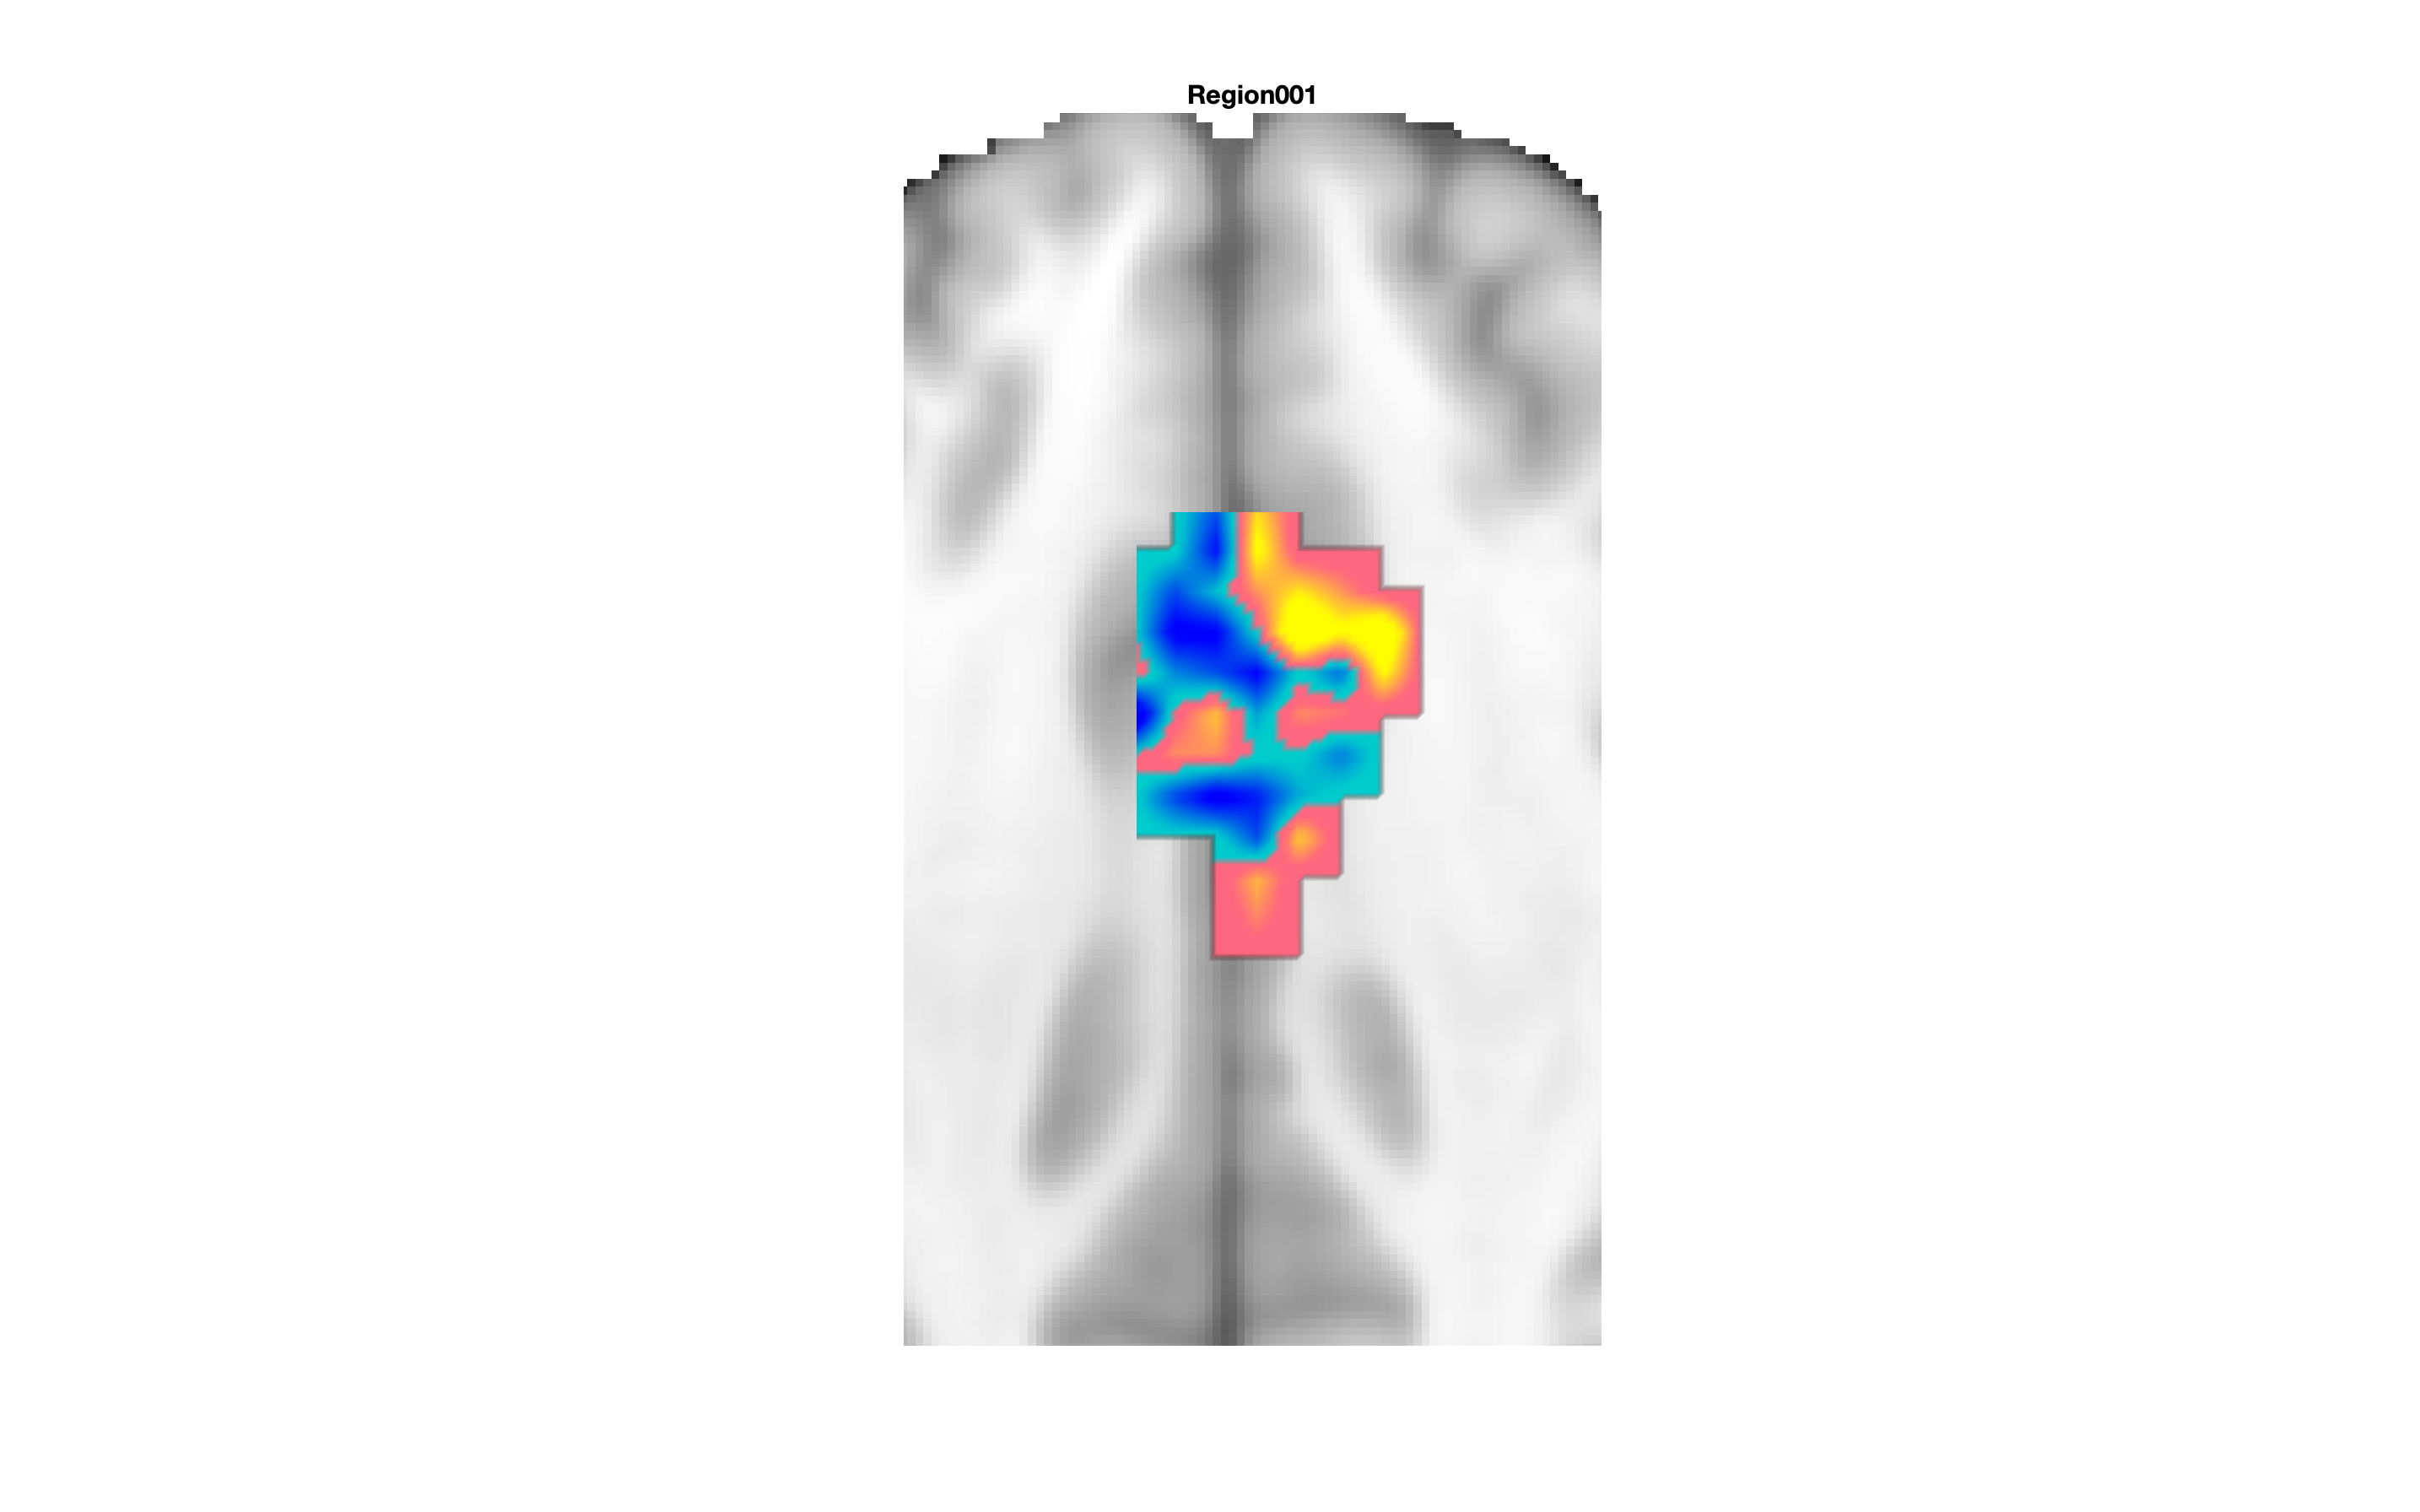


ROC_PLOT Output: Single-interval, Optimal balanced error rate
Threshold:	0.04	Sens:	 57% CI(47%-67%)	Spec:	 57% CI(50%-64%)	PPV:	 40% CI(31%-48%)	Nonparametric AUC:	0.57	Parametric d_a:	0.26	  Accuracy:	 57% +- 3.0% (SE), P = 0.032976
Threshold for cosine_sim = 0.0427, Cohen's d(emo vs no) = 0.26, Bootstrapped CI is [0.01 0.51]
 
                   Cos_Sim_Thresh    Cohens_d     Sensitivity    Specificity      PPV  
                   ______________    _________    ___________    ___________    _______

    Pain              0.039225        -0.25929      0.46667        0.46667      0.30435
    Cog Control       0.039912       0.0027512      0.48889        0.48889      0.32353
    Neg Emotion       0.042662         0.25647      0.56667        0.56667      0.39535



----------------------------------------------
Stats for individual studies
----------------------------------------------


Col   1: ThermalPain1	Col   2: ThermalPain2	Col   3: VisceralPain1	Col   4: VisceralPain2	Col   5: MechanicalPain1	Col   6: MechanicalPain2	Col   7: Cog WM1	Col   8: Cog WM2	Col   9: Cog Inhib1	Col  10: Cog Inhib2	Col  11: Cog RespSel1	Col  12: Cog RespSel2	Col  13: Emotion Aversiveimages1	Col  14: Emotion Aversiveimages2	Col  15: Emotion Rejection1	Col  16: Emotion VicariousPain2	Col  17: Emotion AversiveSound1	Col  18: Emotion AversiveSound2	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
               Name                Mean_Value    Std_Error       T           P         Cohens_d
    ___________________________    __________    _________    _______    __________    ________

    {'ThermalPain1'        

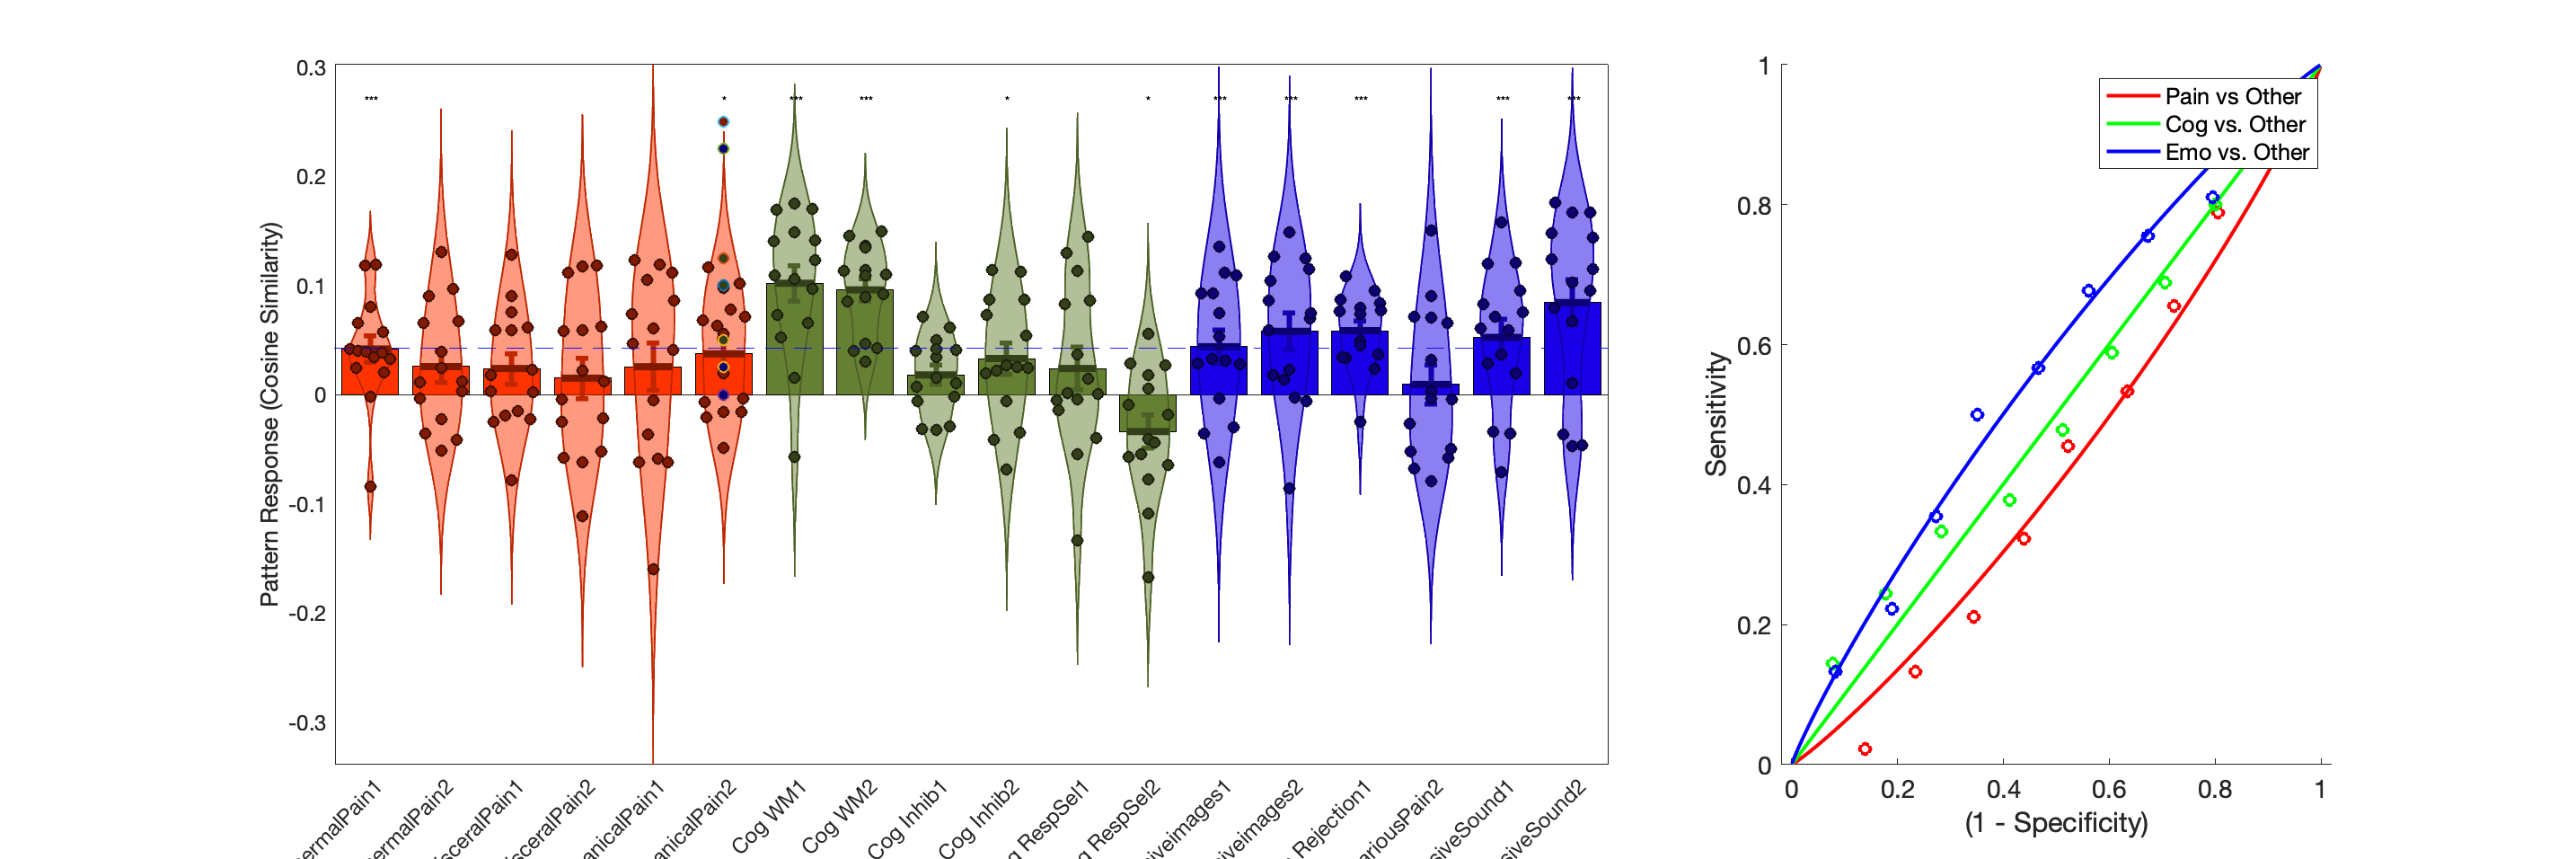

test_pattern_on_kragel_2018_n270_data(obj);

### Visualization of images

f = 'dACC_pain_pattern_wani_121416.nii'; 
obj = fmri_data(f); 

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = 'dACC_pain_pattern_wani_121416.nii'

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 177488 bytes
Loading image number:     1
Elapsed time is 0.036108 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 247  Bit rate: 7.95 bits


create_figure('montage'); axis off
montage(obj); 

Setting up fmridisplay objects


sagittal montage:  37 voxels displayed, 209 not displayed on these slices


sagittal montage:  62 voxels displayed, 184 not displayed on these slices


sagittal montage:  51 voxels displayed, 195 not displayed on these slices


axial montage:  79 voxels displayed, 167 not displayed on these slices


axial montage:  65 voxels displayed, 181 not displayed on these slices


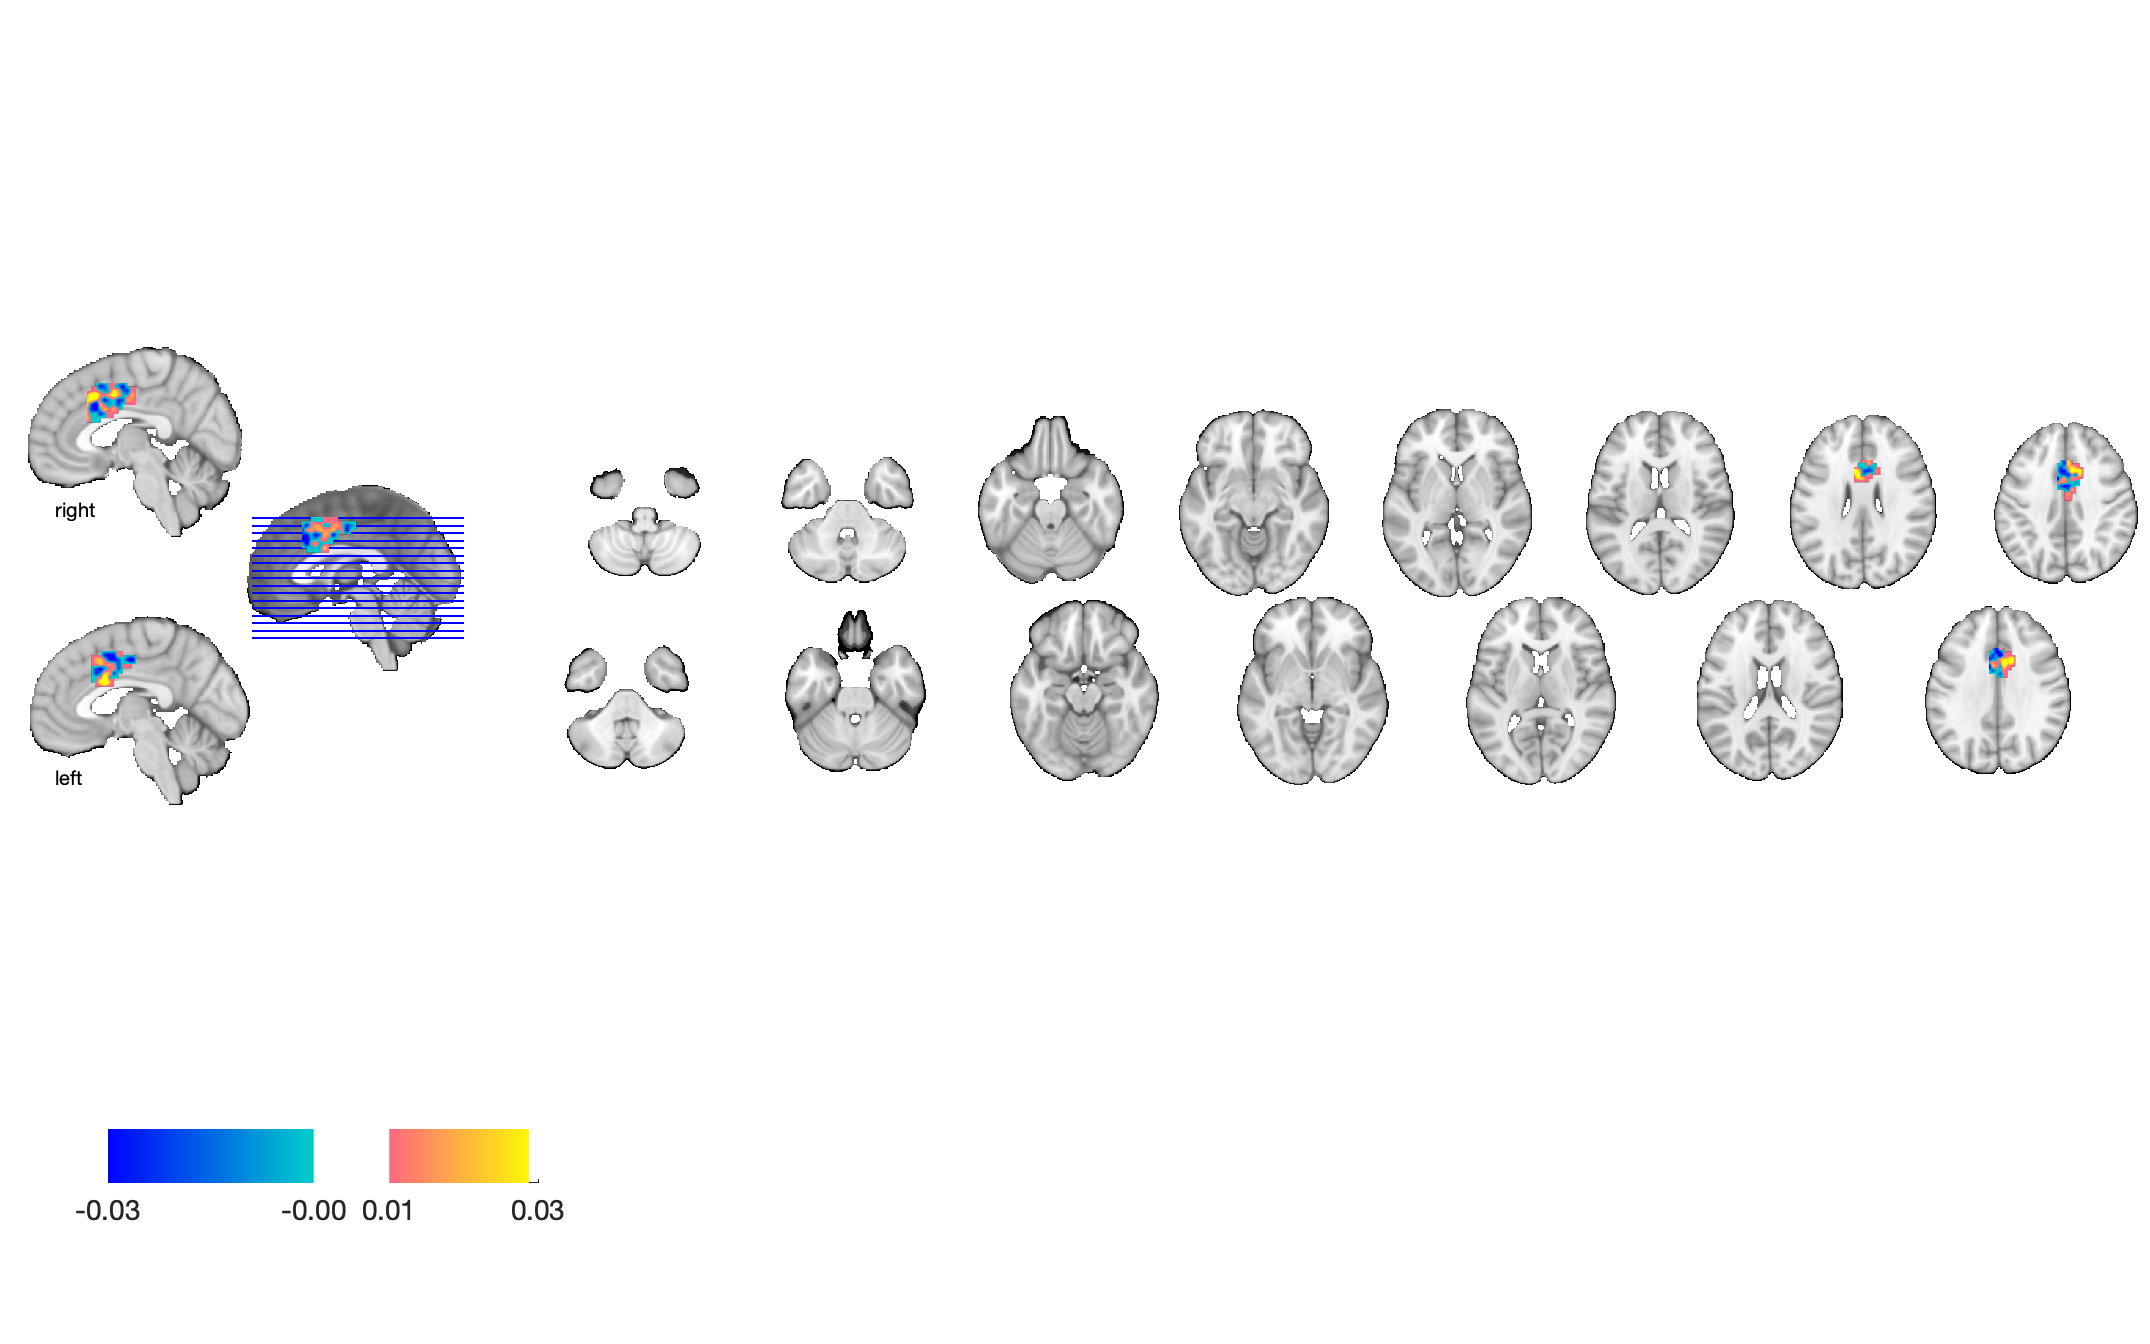

Grouping contiguous voxels:   1 regions



create_figure('montage2'); axis off
montage(region(obj), 'regioncenters', 'colormap');

drawnow


f = 'dACC_task_pattern_wani_121416.nii'; 
obj = fmri_data(f); 

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = 'dACC_task_pattern_wani_121416.nii'

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 177488 bytes
Loading image number:     1
Elapsed time is 0.028957 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 247  Bit rate: 7.95 bits


create_figure('montage'); axis off
montage(obj); 

Setting up fmridisplay objects


sagittal montage:  37 voxels displayed, 209 not displayed on these slices


sagittal montage:  62 voxels displayed, 184 not displayed on these slices


sagittal montage:  51 voxels displayed, 195 not displayed on these slices


axial montage:  79 voxels displayed, 167 not displayed on these slices


axial montage:  65 voxels displayed, 181 not displayed on these slices


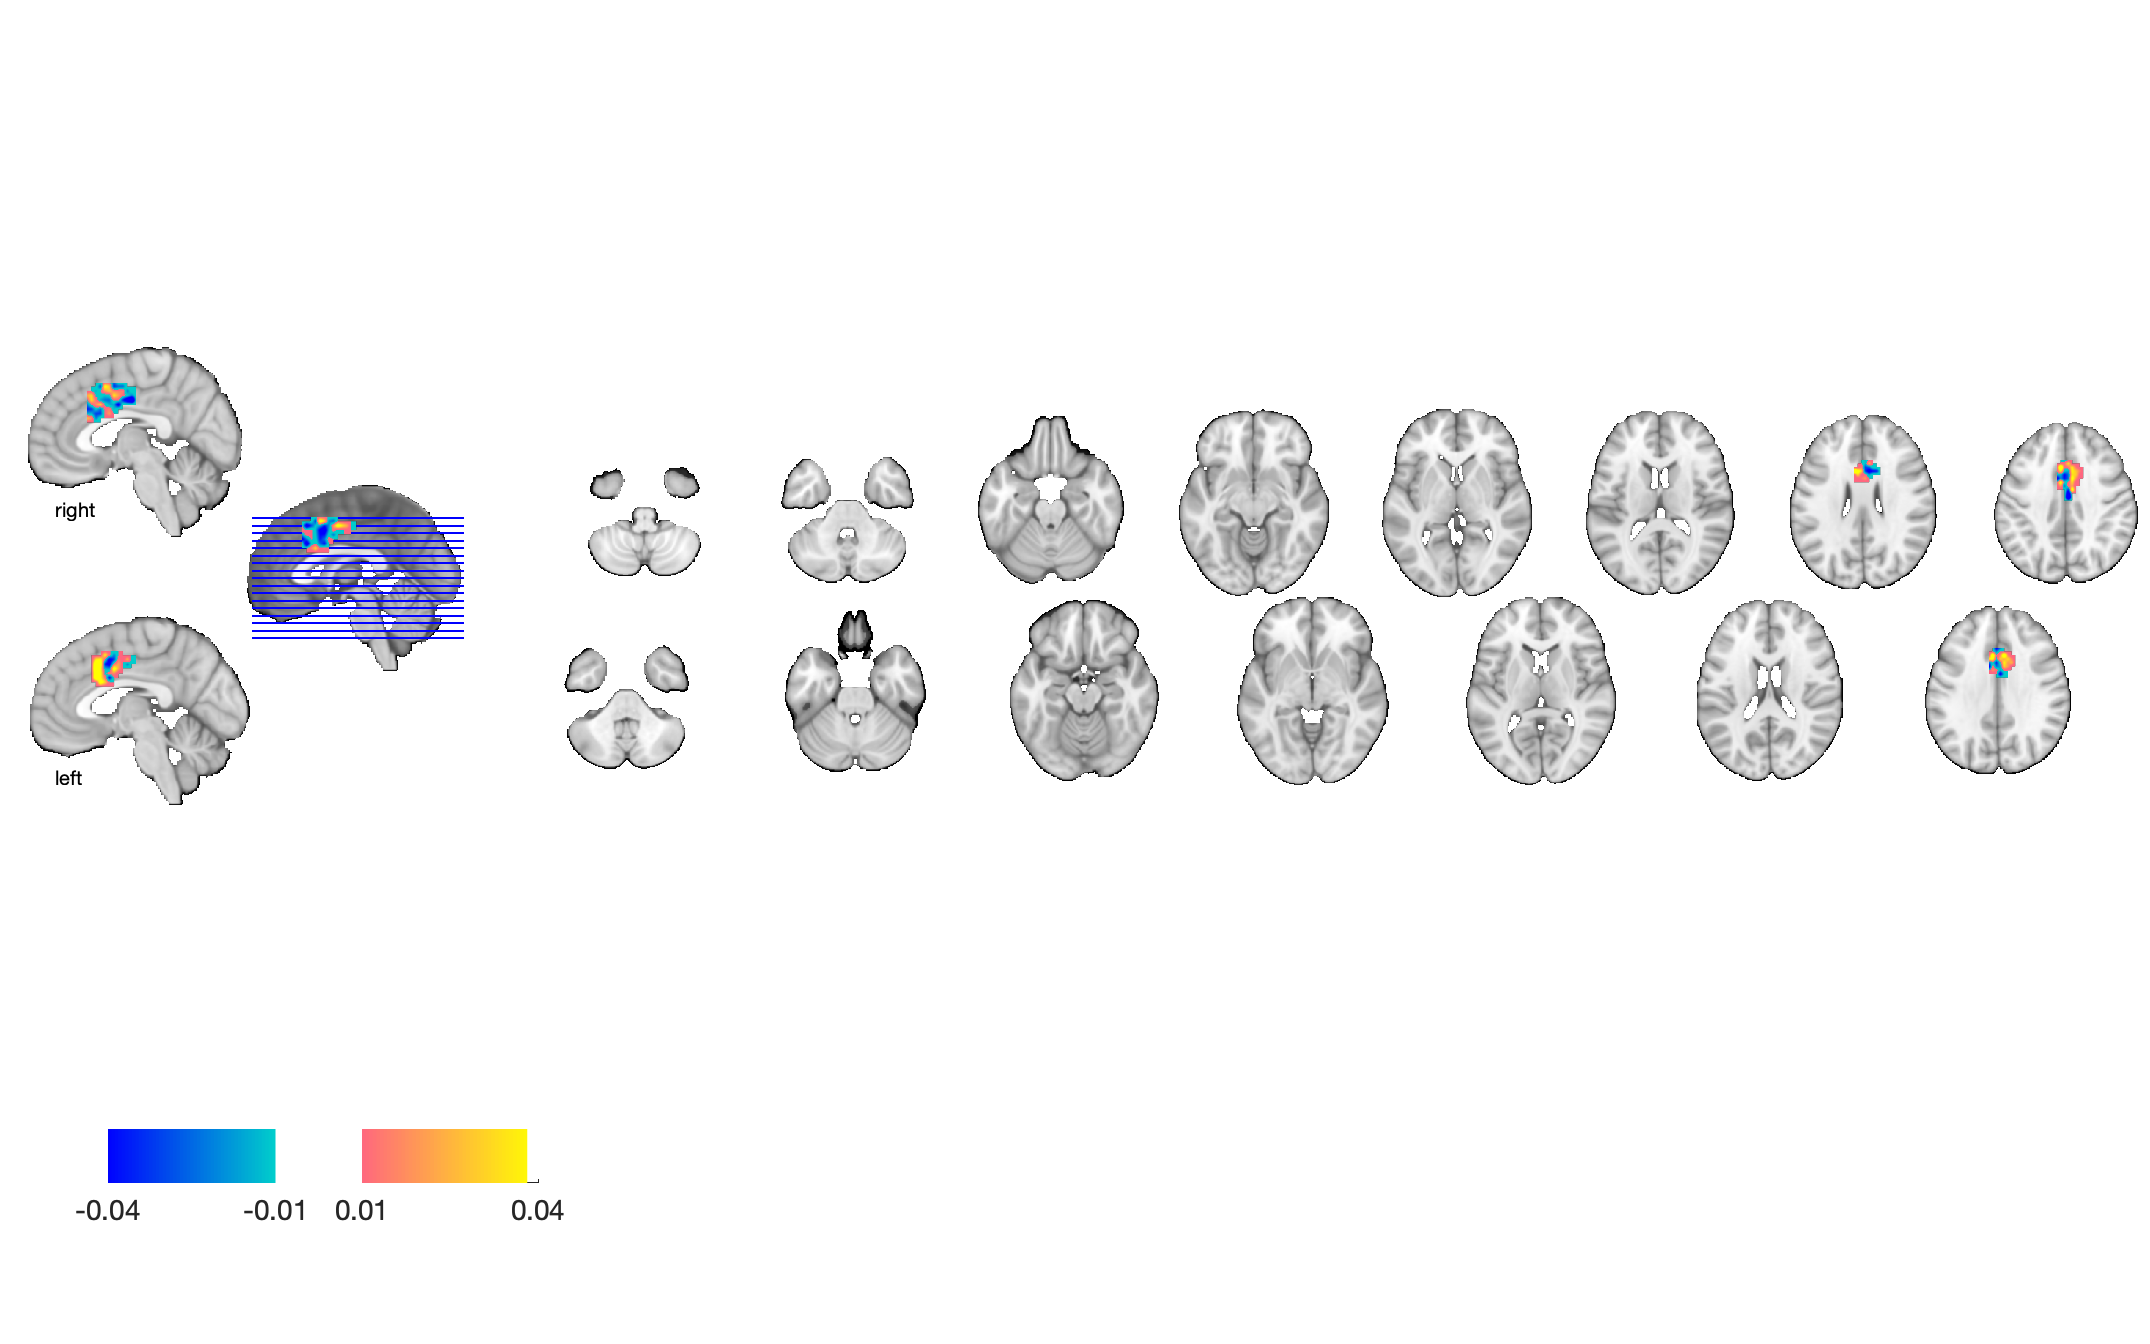

Grouping contiguous voxels:   1 regions


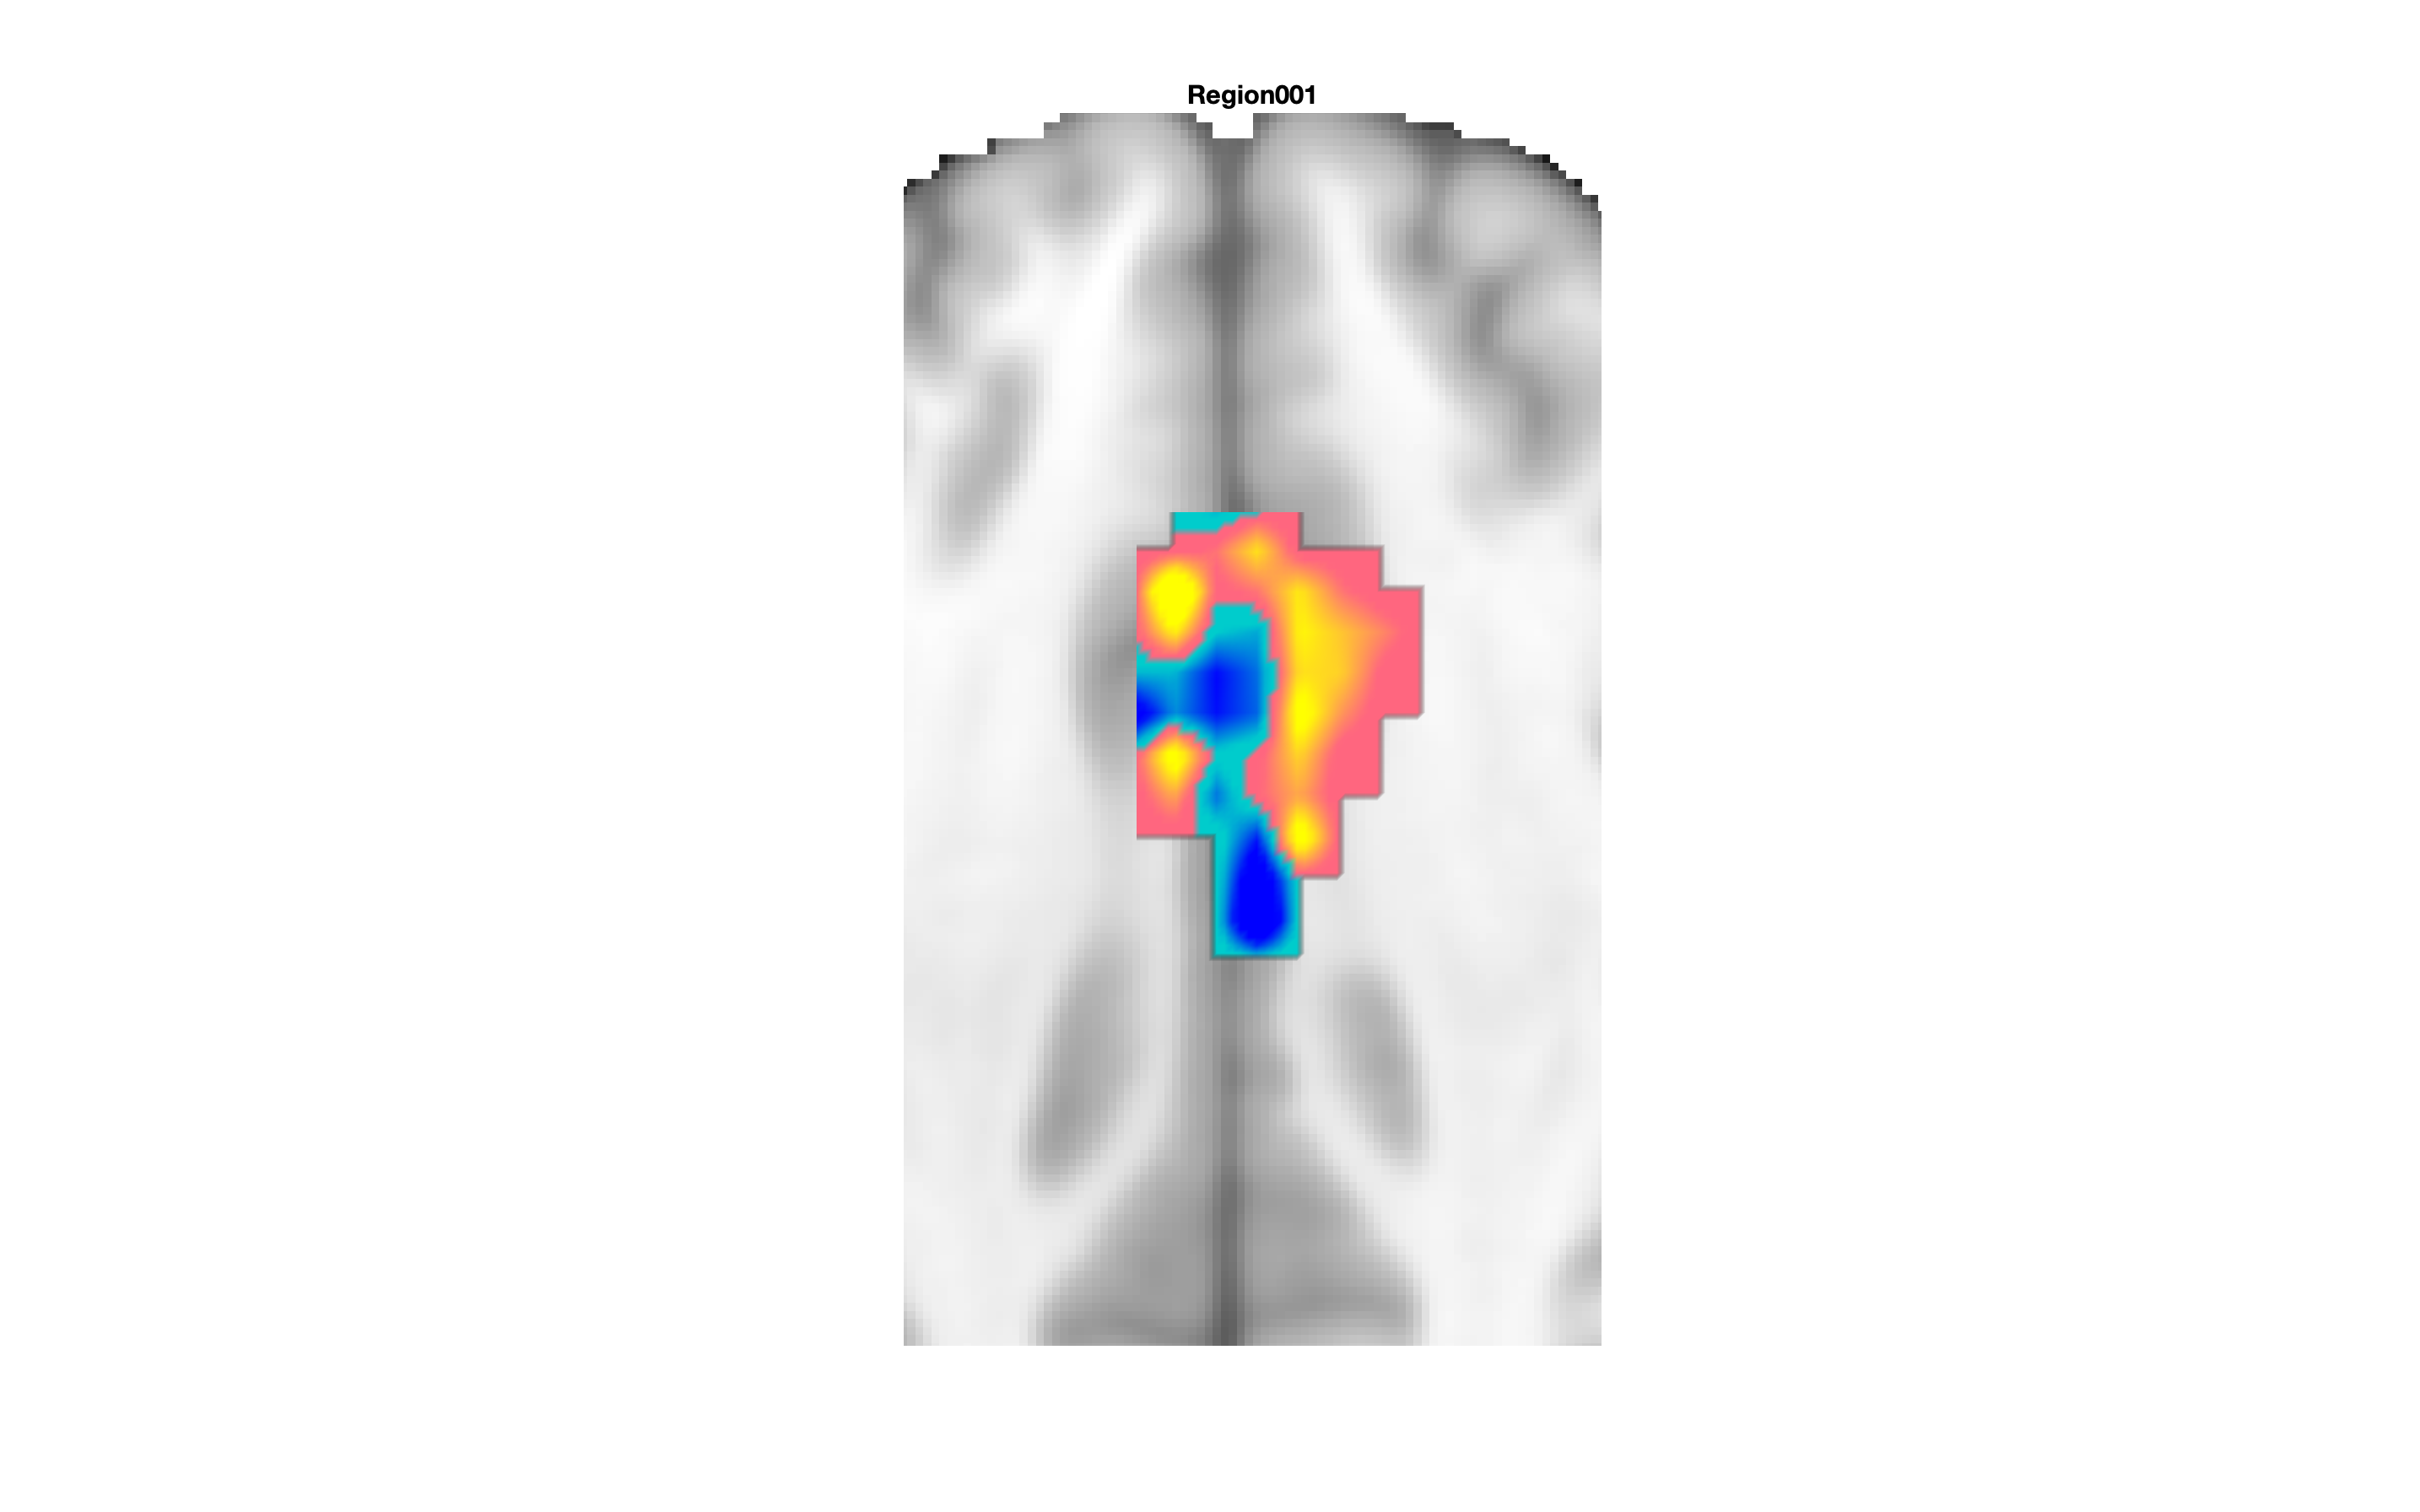


create_figure('montage2'); axis off
montage(region(obj), 'regioncenters', 'colormap');

drawnow


f = 'stroop_pattern_wani_121416.nii';
obj = fmri_data(f); 

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 


sampleto = 'stroop_pattern_wani_121416.nii'

Defaults settings have been modified by file(s):
  /Users/torwager/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 177488 bytes
Loading image number:     1
Elapsed time is 0.032031 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 1878  Bit rate: 10.87 bits


create_figure('montage'); axis off
montage(obj); 

Setting up fmridisplay objects


sagittal montage:  65 voxels displayed, 1812 not displayed on these slices


sagittal montage:  68 voxels displayed, 1809 not displayed on these slices


sagittal montage:  72 voxels displayed, 1805 not displayed on these slices


axial montage: 500 voxels displayed, 1377 not displayed on these slices


axial montage: 556 voxels displayed, 1321 not displayed on these slices


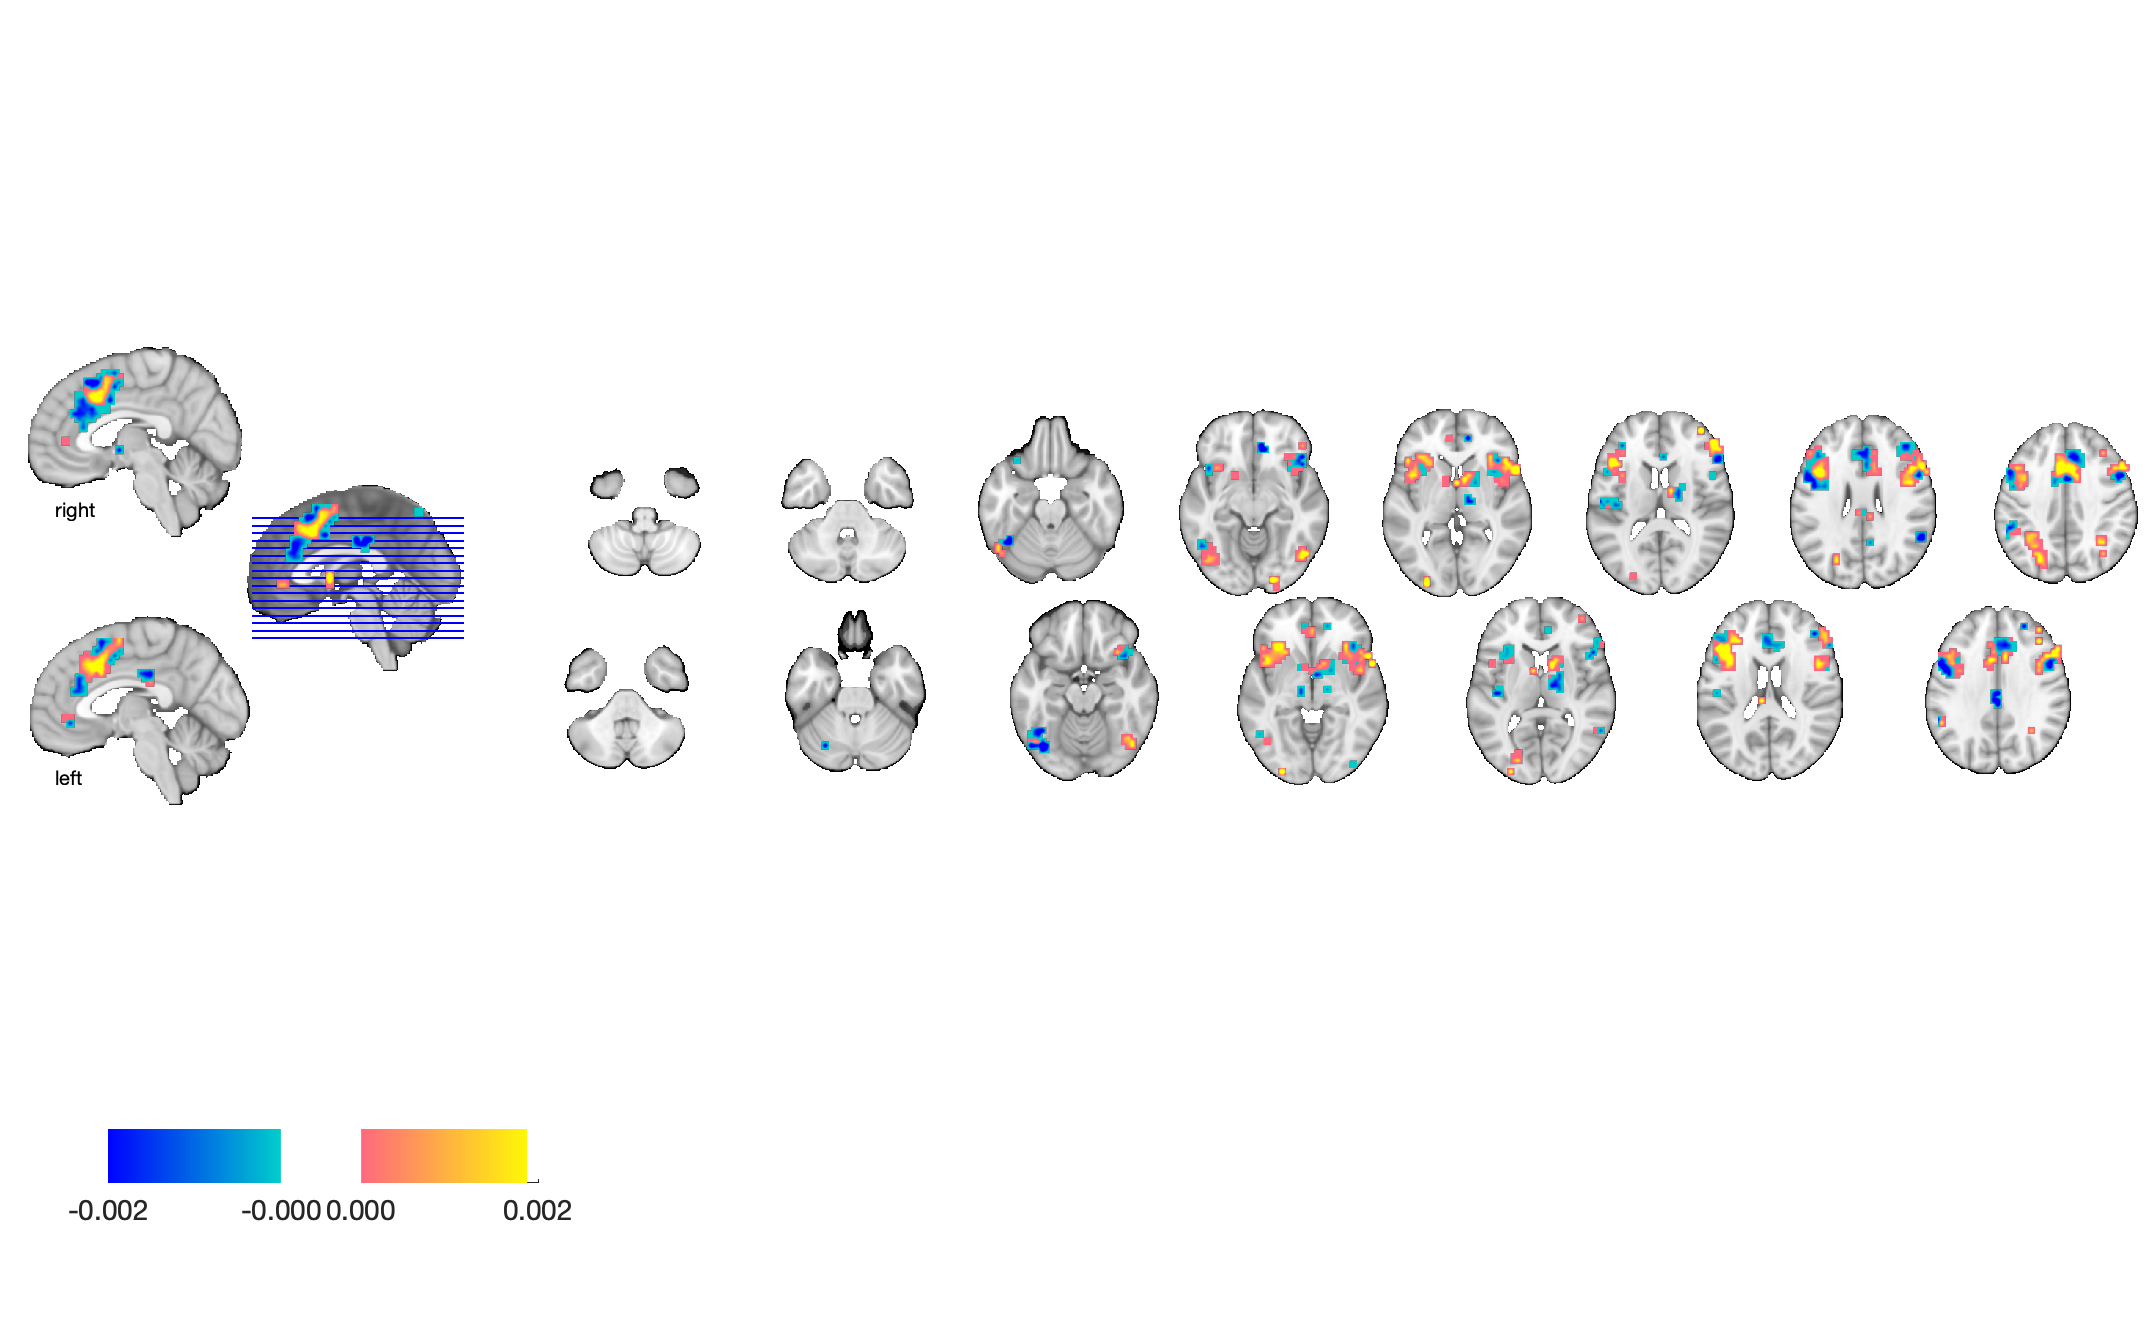

Grouping contiguous voxels:  61 regions


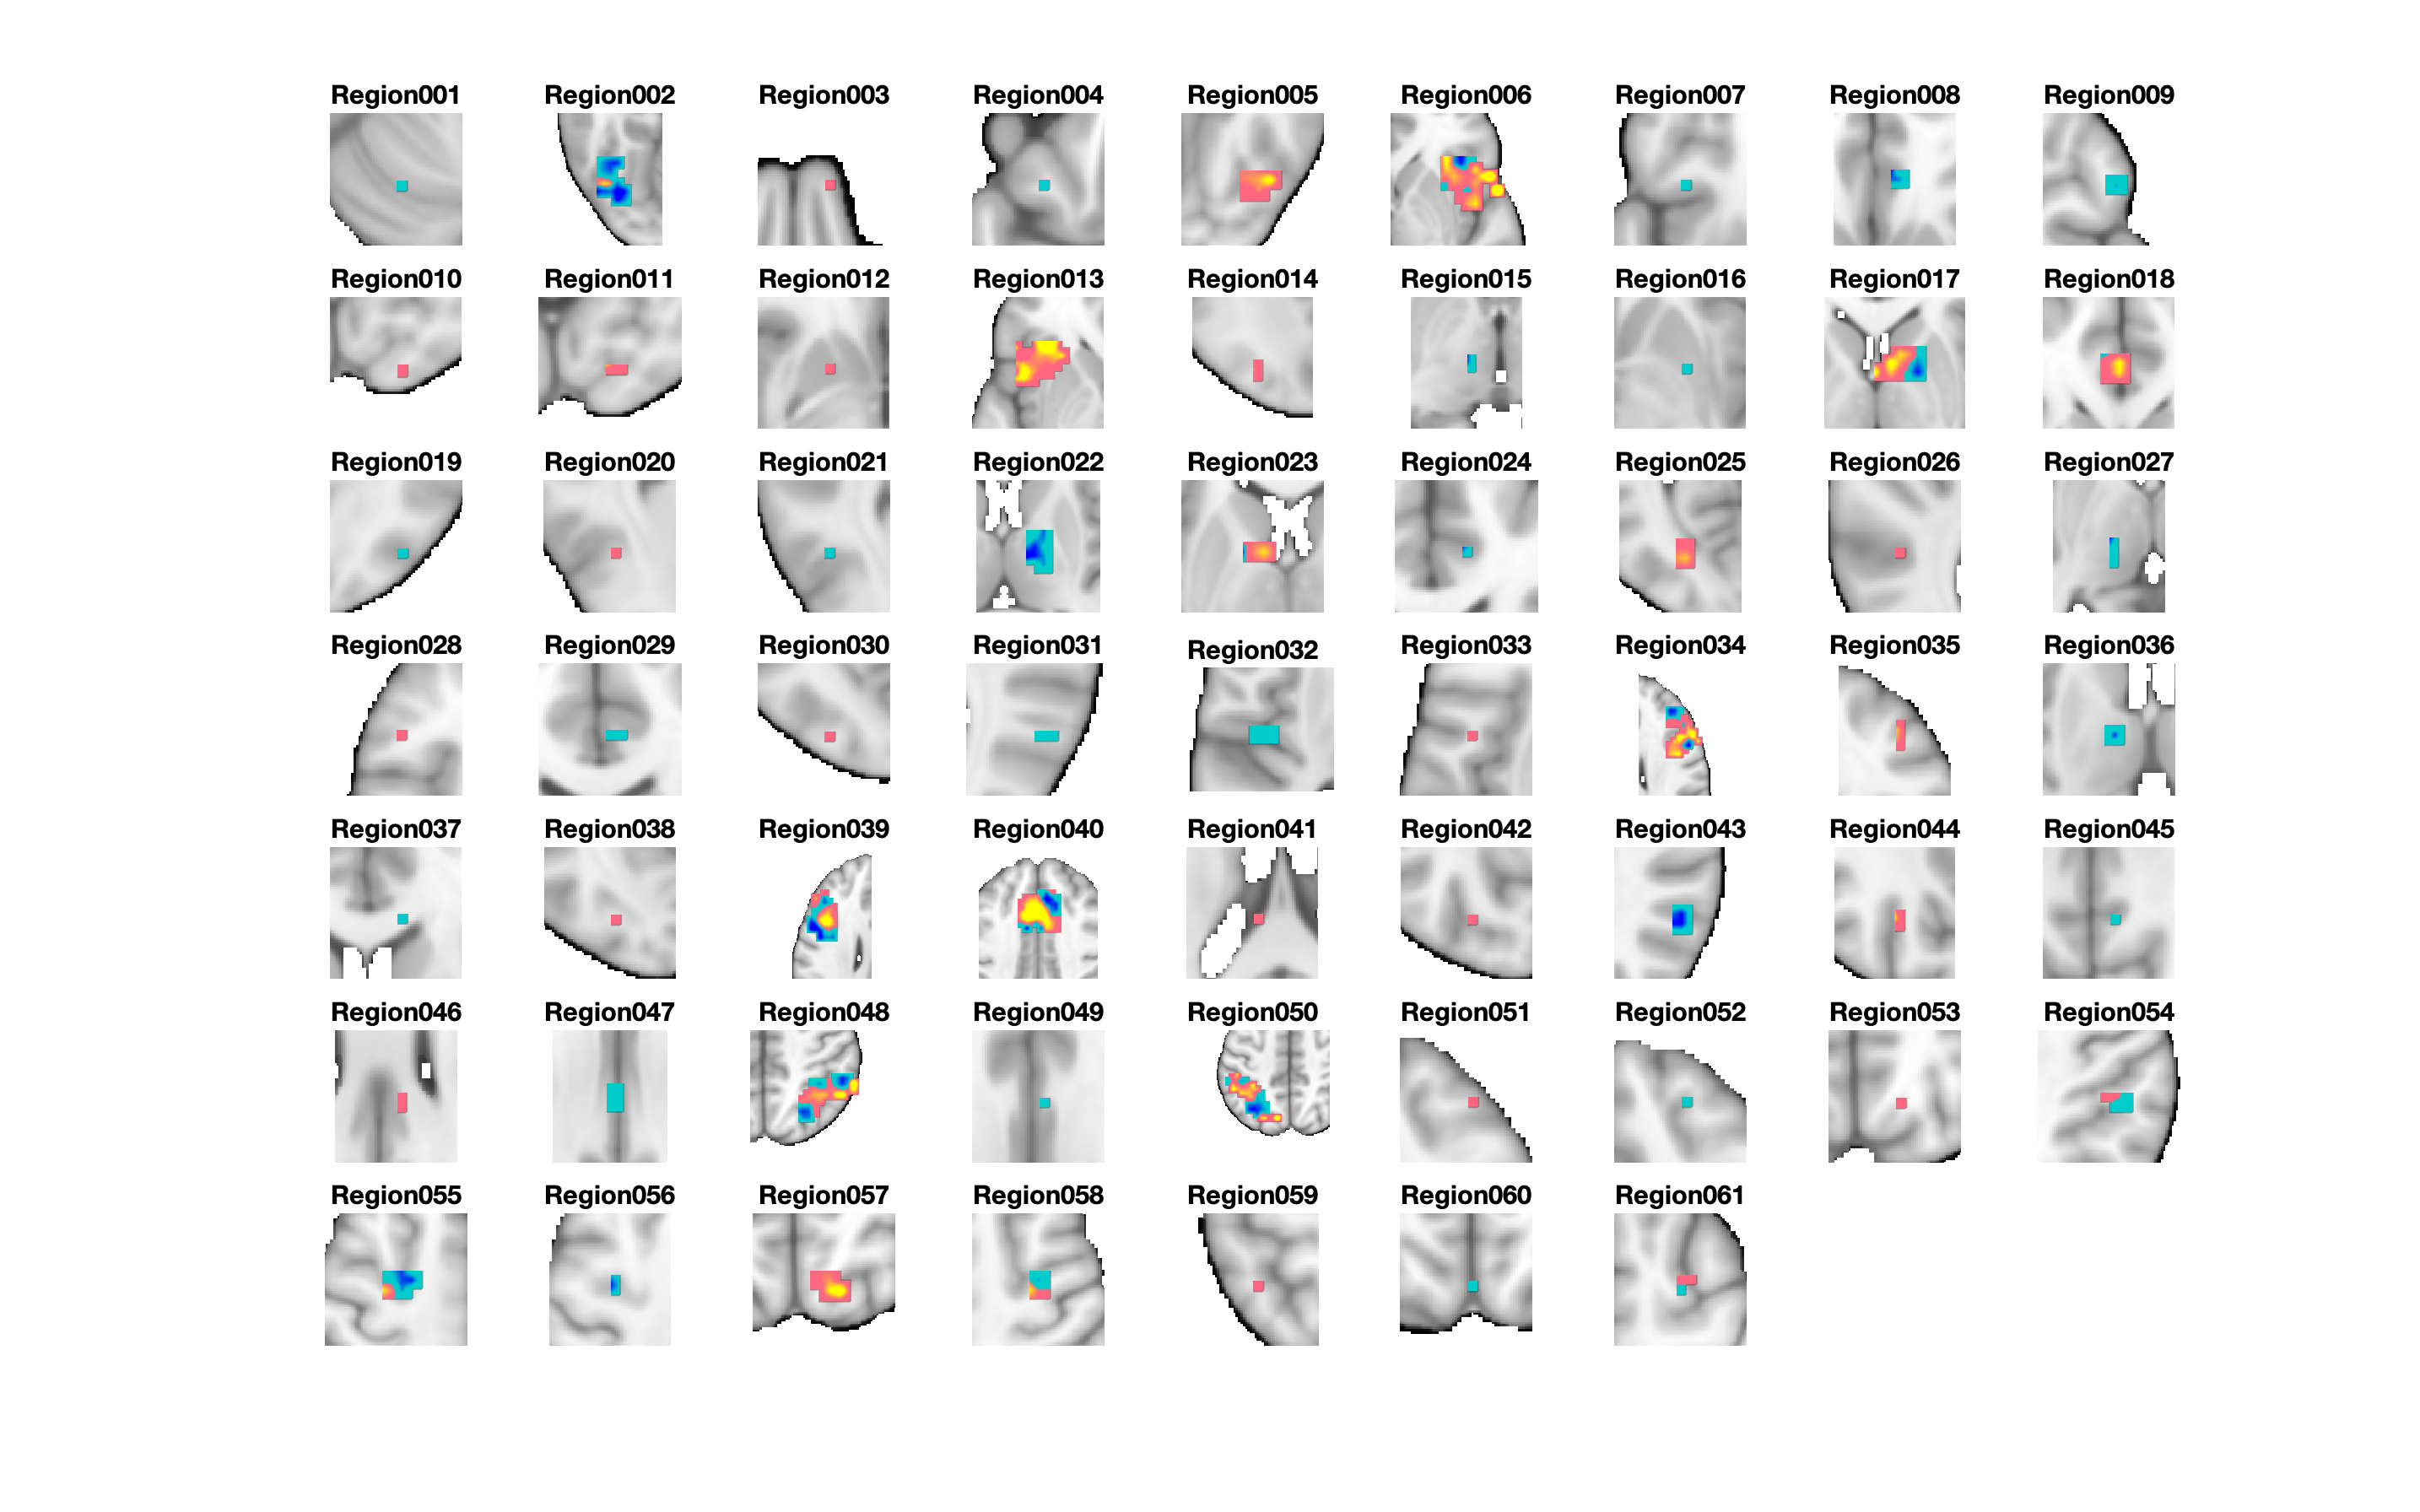


create_figure('montage2'); axis off
montage(region(obj), 'regioncenters', 'colormap');

drawnow